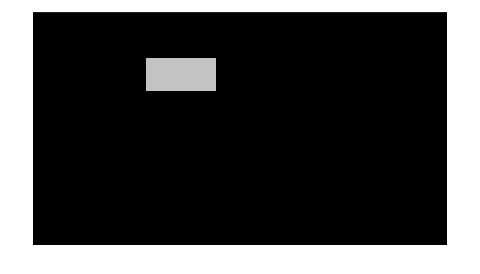

% Ex2
clear variables

im = imread('Rectangle.png');
imshow(im)

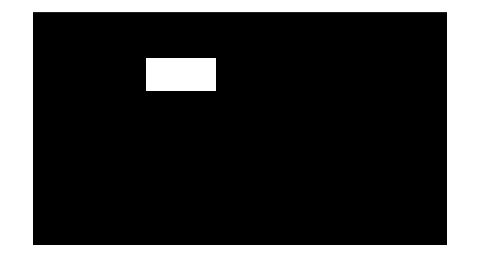

if(~islogical(im))
    if(ndims(im) > 2), im = rgb2gray(im); end
        level = graythresh(im); BW = im2bw(im,level);
    else
        BW = im;
end
figure , imshow(BW)

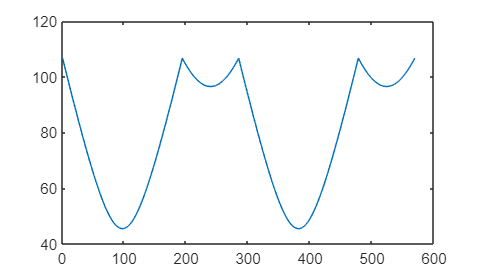

N = 10;
[B,L,N] = bwboundaries(BW,'noholes');
stats = regionprops(BW,'Centroid');
coordinates = stats(1).Centroid;
xc = coordinates(1);
yc = coordinates(2);
X = B{1}(:,2);
Y = B{1}(:,1);
r = zeros(length(X), 1);
for k = 1: length(X)
    r(k) = sqrt((X(k)-xc)^2 + (Y(k)-yc)^2);
end
plot(r);